4.7 Definition af måleusikkerhed, systematiske fejl og tilfældige fejl

Hvilke af følgende udsagn om måleusikkerhed, tilfældige effekter og systematiske effekter er korrekte?

A. Korrekt estimeret måleusikkerhed tager hensyn til både tilfældige og systematiske effekter.

Ja

B. I praksis er det muligt at eliminere alle usikkerhedskilder, så måleresultater ikke har nogen usikkerhed.

Nej

C. Systematiske effekter kan minimeres (eller endda elimineres) ved at udføre mange gentagelser af målingen.

Ja

D. Tilfældige effekter kan aldrig helt elimineres, men deres indflydelse på resultatet kan reduceres ved at foretage flere gentagne målinger.

Ja 

E. Målingen kan principielt korrigeres for systematiske effekter

Ja

F. Målingen kan principielt korrigeres for tilfældige effekte

Nej

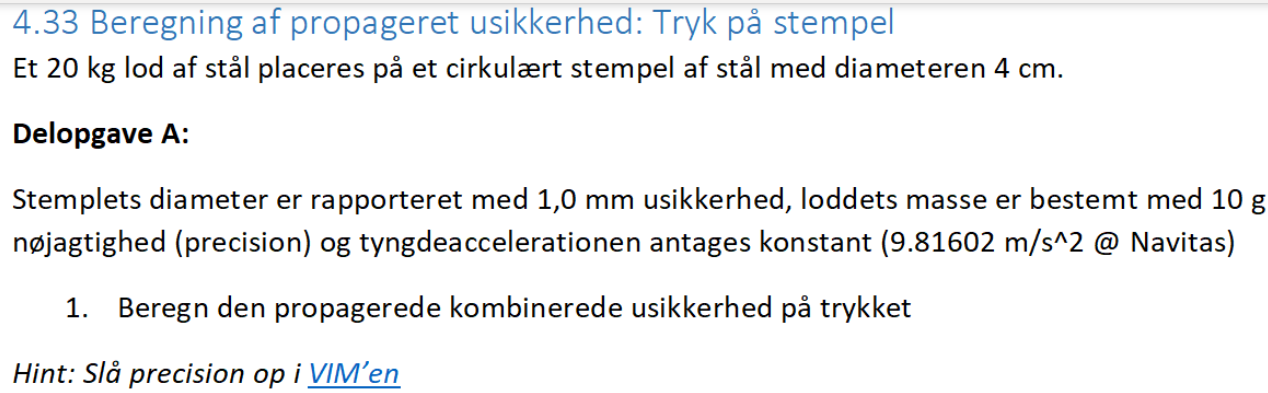

clear all
m = 20; %kg
u_m = 10 / 1000; %kg
d = 4/100; %m
u_d = 1/1000; %m

g = 9.81602; %m/s^2

F = m * g % N

F = 196.3204

A = pi * (d/2)^2

A = 0.0013

Tryk = F/A

Tryk = 1.5623e+05

syms m_sym d_sym h_sym
F = m_sym * g; % N
A = pi * (d_sym/2)^2;
Tryk_sym = F/A;


vars = symvar(Tryk_sym)

$$vars = \left(\begin{array}{cc} d_{\mathrm{sym}} & m_{\mathrm{sym}} \end{array}\right)$$

% U_Tryk = STAT.Ophobningsloven(Tryk_sym, vars, [d m], [u_d u_m]);
% vpa(U_Tryk)
Vars = [[d_sym, d, u_d]
        [m_sym, m, u_m]];
Vars(2,1)

$$ans = m_{\mathrm{sym}}$$

[y, u_y] = STAT.Ophobningsloven_m(Tryk_sym, Vars)

n = 2

156226.8±7811.73

y = 1.5623e+05

u_y = 7.8117e+03